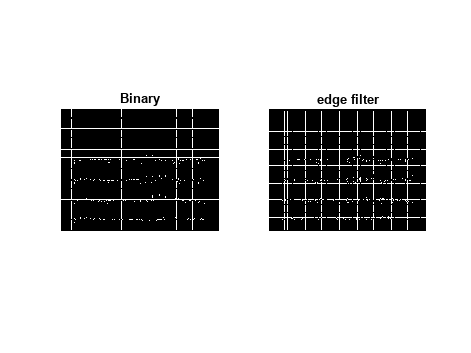

clc; clear; close all
filename = input('Enter filename: ', 's');
pix = imread(filename);
[height, width, color] = size(pix);
binary = false(height, width);
for ii=1:1:height
    for jj=1:1:width
        red = pix(ii, jj, 1);
        green = pix(ii, jj, 2);
        blue = pix(ii, jj, 3);
        if blue < 55 && red < 55 && green < 55
            binary(ii, jj)= 1;
        end
    end
end
figure;
subplot(1,2,1);
imshow(binary)
title("Binary")
imgdata = binary;

     %EDGE FILTER
I_filtered = edge(imgdata, "canny", [], 2);
subplot(1,2,2);
imshow(I_filtered);
title("edge filter");

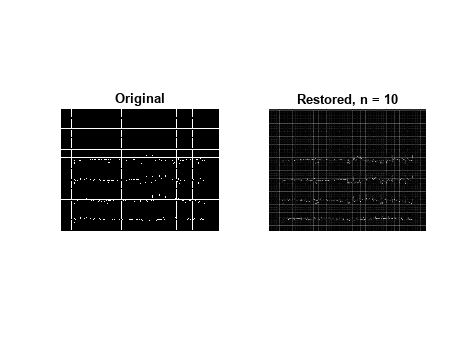

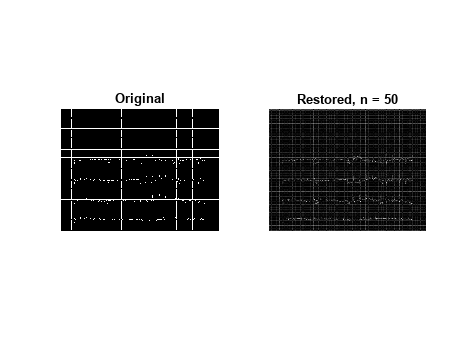

Error using imboxfilt
Expected A to be one of these types:

uint8, uint16, uint32, int8, int16, int32, single, double

Instead its type was logical.

Error in imboxfilt>validateImage (line 208)
validateattributes(A, supportedTypes, supportedAttributes, mfilename, 'A');

Error in imboxfilt>parseInputs (


     %METZ FILTER
sigma = 2;
[x,y] = meshgrid(-111:110, -111:110);
h = exp(-(x.^2 + y.^2) / (2*sigma^2)) / (2*pi*sigma^2);
n = [10, 50];
for n_temp = n
    H = fft2(h, 1700, 2200);
    F = fft2(double(imgdata));
    G = ifft2(F .* (1-(1-abs(H).^2).^n_temp)./abs(H));
    figure;
    colormap gray
    subplot(1, 2, 1);
    imagesc(imgdata);
    title("Original");
    axis image off;
    subplot(1, 2, 2);
    imagesc(abs(G));
    title("Restored, n = " + num2str(n_temp));
    axis image off
end